# Example: COVID-2019 data for US

I am still taking some data from John Hopkins university [1]. However, the format for the US data is different and not consistent. So the database may be updated in the next few days.

As far as I know (at last on 2020-03-04), no data for the recovered cases are (yet) available. The function fit_SEIQRDP is modified to account for this possibility. If the Recovered cases are missing, the recovery rate is set as a constant, i.e. lambda0(2) is no longer used. This should avoid an overparametrization of the model.

[1] [https://github.com/CSSEGISandData/COVID-19](https://github.com/CSSEGISandData/COVID-19)

## Access the Data from the database

The parameters are here taken as constant except the death rate.

clearvars;close all;clc;
[tableConfirmed,tableDeaths,tableRecovered,time] = getDataCOVID_US();
timeRef = time;

## Choice of New York City

time = timeRef;

fprintf(['Most recent update: ',datestr(time(end)),'\n'])

Most recent update: 04-Apr-2020


Location = 'New York City, New York, US';
try
    indC = find(contains(tableConfirmed.Combined_Key,Location)==1);
    indD = find(contains(tableDeaths.Combined_Key,Location)==1);
catch exception
    searchLoc = strfind(tableConfirmed.Combined_Key,Location);
    indC = find([searchLoc{:}]==1);
    
    searchLoc = strfind(tableConfirmed.Combined_Key,Location);
    indD = find([searchLoc{:}]==1);
end

disp(tableConfirmed(indC,11));

            Combined_Key         
    _____________________________

    "New York City, New York, US"



inC = indC(1);

Deaths = table2array(tableDeaths(indD,13:end));
Confirmed = table2array(tableConfirmed(indC,12:end));
Npop= table2array(tableDeaths(indD,12)); % population (dummy number here)

## Initial conditions for the fitting

% If the number of confirmed Confirmed cases is small, it is difficult to know whether
% the quarantine has been rigorously applied or not. In addition, this
% suggests that the number of infectious is much larger than the number of
% confirmed cases
minNum= round(0.025*max(Confirmed)); % 5% of the maximal number of confirmed is used for the initial conditions
Deaths(Confirmed<=minNum)=[];
time(Confirmed<=minNum)= [];
Confirmed(Confirmed<=minNum)=[];

fprintf(['Population = ',num2str(Npop),' \n'])

Population = 5803210 


% Definition of the first estimates for the parameters
alpha_guess = 0.05;
beta_guess = 0.8; % Infection rate
LT_guess = 5; % latent time in days
QT_guess = 30; % quarantine time in days
lambda_guess = [0.1,0.03]; % recovery rate
kappa_guess = [0.07,0.03]; % death rate

guess = [alpha_guess,...
    beta_guess,...
    1/LT_guess,...
    1/QT_guess,...
    lambda_guess,...
    kappa_guess];

E0 = Confirmed(1); % Initial number of exposed cases. Unknown but unlikely to be zero.
I0 = Confirmed(1); % Initial number of infectious cases. Unknown but unlikely to be zero.
Q0 = Confirmed(1);
R0 = Deaths(1); % Unknown but unlikely to be zero. Taken as equal to the number of deaths
D0 = Deaths(1);

% Parameter estimation with the lsqcurvefit function
[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1] = ...
    fit_SEIQRDP(Confirmed-Deaths,[],Deaths,Npop,E0,I0,time,guess);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          9     1.33623e+10                      4.34e+10
     1         18     2.20332e+09       0.374463       9.48e+09      
     2         27     1.25621e+09       0.615444       6.54e+09      
     3         36     3.18412e+08       0.522343       5.34e+09      
     4         45     3.18412e+08       0.407853       5.34e+09      
     5         54     2.16768e+08       0.101963        1.2e+09      
     6         63     1.26939e+08       0.203927       3.91e+08      
     7         72     3.39559e+07       0.351082       1.75e+08      
     8         81     2.54897e+07       0.407853       1.12e+08      
     9         90     2.49123e+07       0.815707       6.93e+08      
    10         99      1.0953e+07       0.203927        4.9e+07      
    11        108     5.64087e+06       0.398393       2.64e+09      
    12        117     4.13075e+0

Simulate the epidemy outbreak based on the fitted parameters

dt = 0.1; % time step
time1 = datetime(time(1)):dt:datetime(datestr(floor(datenum(now))+datenum(10)));
N = numel(time1);
t = [0:N-1].*dt;
[S,E,I,Q,R,D,P] = SEIQRDP(alpha1,beta1,...
    gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,Q0,R0,D0,t);

##  Comparison of the fitted and real data

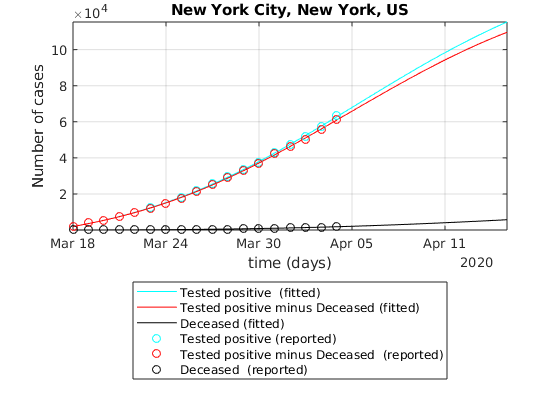

figure
semilogy(time1,Q+R+D,'c',time1,Q+R,'r',time1,D,'k');
hold on
semilogy(time,Confirmed,'co',time,Confirmed-Deaths,'ro',time,Deaths,'ko');
% ylim([0,1.1*Npop])
ylabel('Number of cases')
xlabel('time (days)')
leg = {'Tested positive  (fitted)','Tested positive minus Deceased (fitted)',...
    'Deceased (fitted)',...
    'Tested positive (reported)',...
    'Tested positive minus Deceased  (reported)','Deceased  (reported)'};
legend(leg{:},'location','southoutside')
set(gcf,'color','w')
grid on
axis tight
title([Location])
set(gca,'yscale','lin')

## Case of multiple cities

The fitting is more challenging and uncertainties are increased because the number of recovered is unknown. In particular, the sensitivity on the initial guess is quite high. I have limited trust in the results provided by fit_SEIQRDP.

time = timeRef;
fprintf(['Most recent update: ',datestr(time(end)),'\n'])

Most recent update: 04-Apr-2020


            Combined_Key         
    _____________________________

    "Los Angeles, California, US"



Population = 10039107 


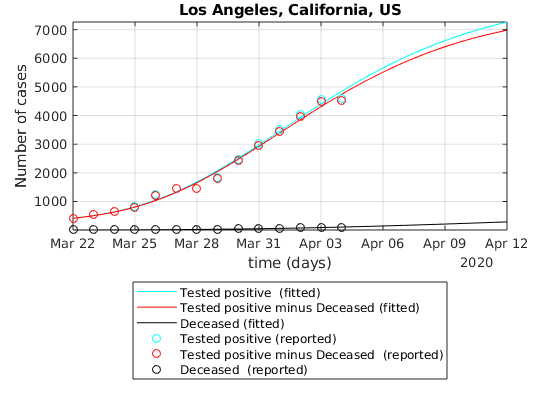

            Combined_Key        
    ____________________________

    "Fairfield, Connecticut, US"



Population = 943332 


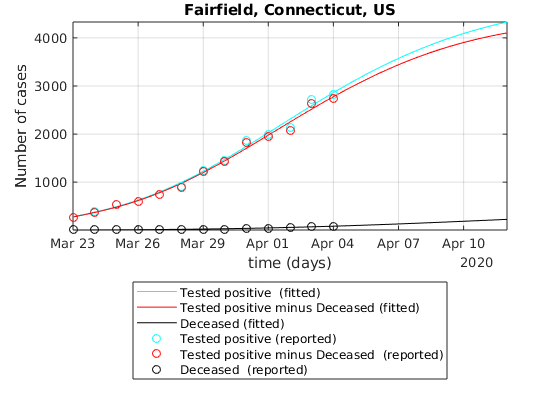

          Combined_Key       
    _________________________

    "Miami-Dade, Florida, US"



Population = 2716940 


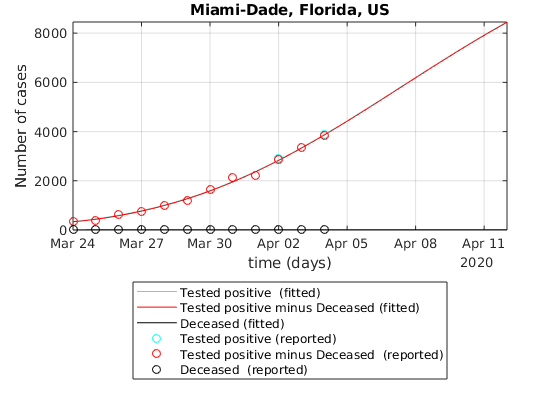

        Combined_Key    
    ____________________

    "Cook, Illinois, US"



Population = 5150233 


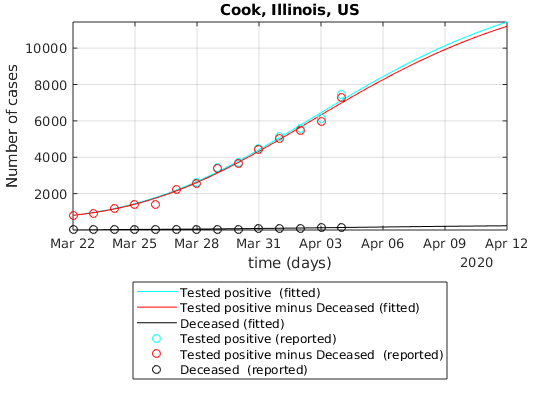

           Combined_Key       
    __________________________

    "Jefferson, Louisiana, US"



Population = 432493 


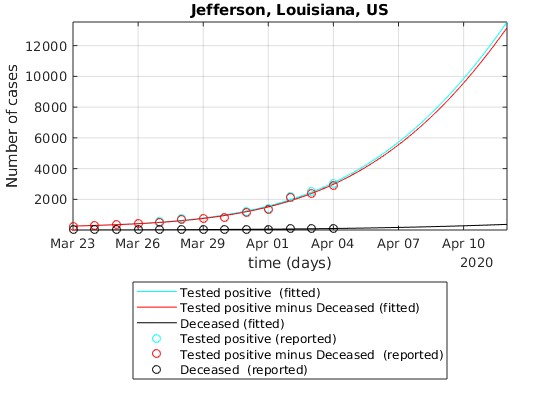

          Combined_Key      
    ________________________

    "Orleans, Louisiana, US"



Population = 390144 


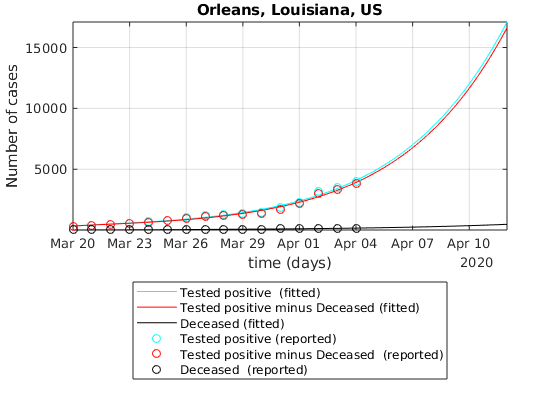

         Combined_Key      
    _______________________

    "Oakland, Michigan, US"



Population = 1257584 


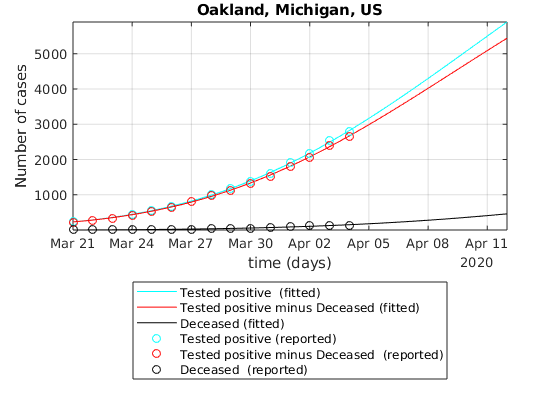

        Combined_Key     
    _____________________

    "Wayne, Michigan, US"



Population = 1749343 


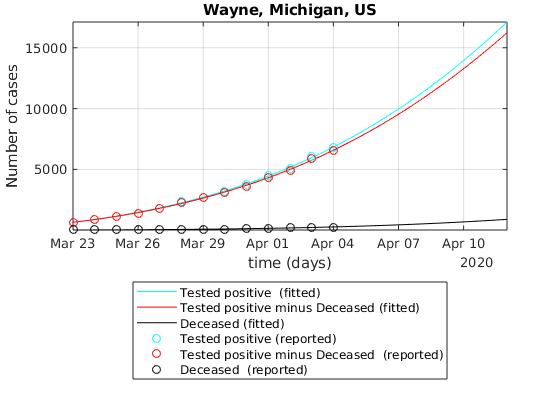

          Combined_Key      
    ________________________

    "Bergen, New Jersey, US"



Population = 932202 


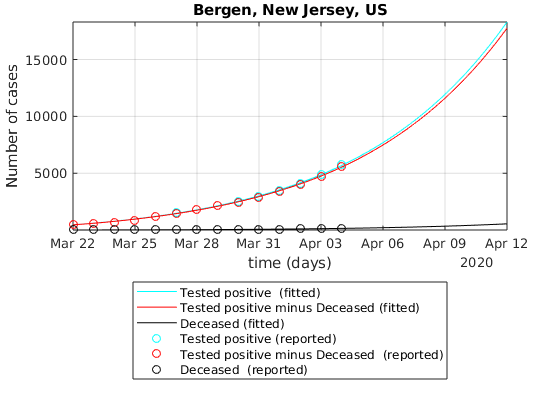

         Combined_Key      
    _______________________

    "Essex, New Jersey, US"



Population = 798975 


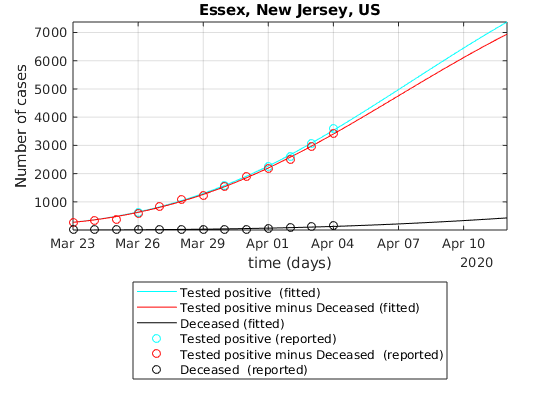

          Combined_Key       
    _________________________

    "Passaic, New Jersey, US"



Population = 501826 


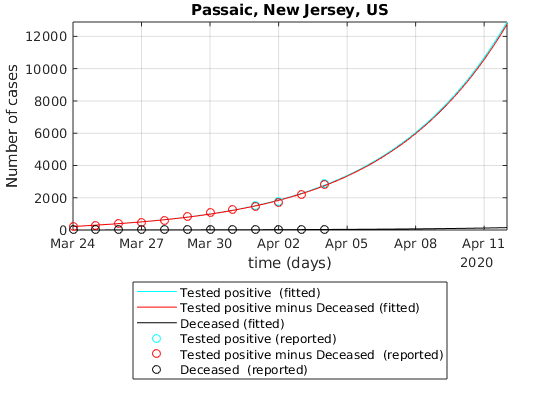

         Combined_Key      
    _______________________

    "Union, New Jersey, US"



Population = 556341 


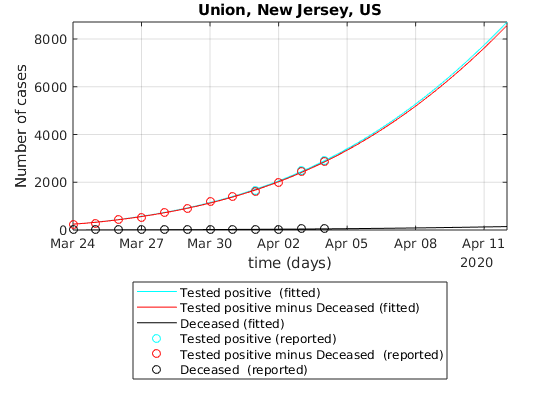

         Combined_Key     
    ______________________

    "Nassau, New York, US"



Population = 1356924 


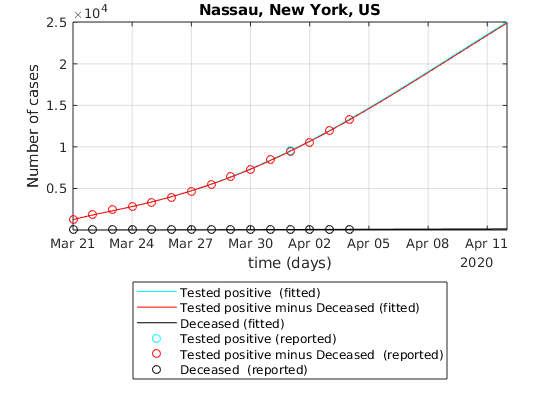

            Combined_Key         
    _____________________________

    "New York City, New York, US"



Population = 5803210 


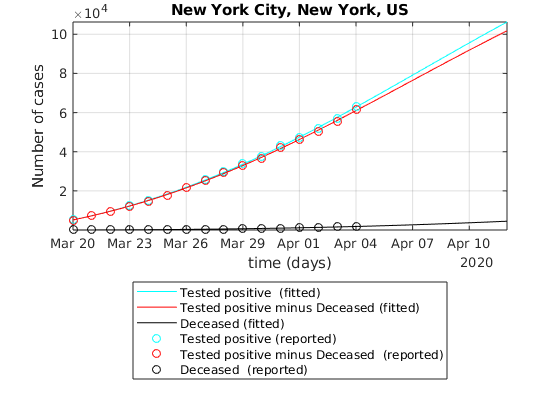

         Combined_Key     
    ______________________

    "Orange, New York, US"



Population = 384940 


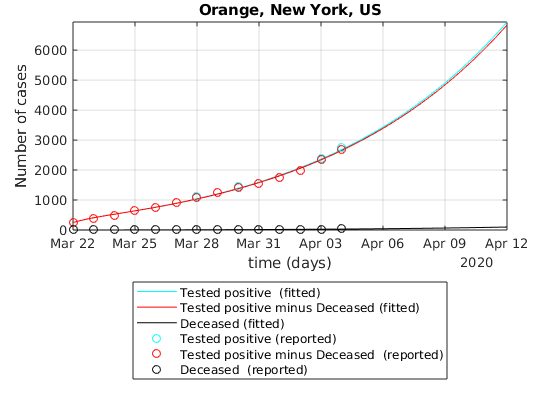

          Combined_Key      
    ________________________

    "Rockland, New York, US"



Population = 325789 


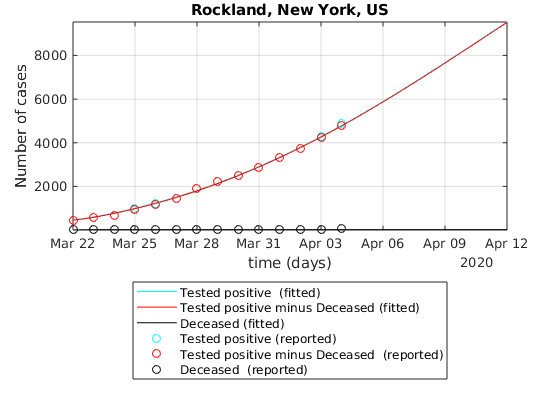

         Combined_Key      
    _______________________

    "Suffolk, New York, US"



Population = 1476601 


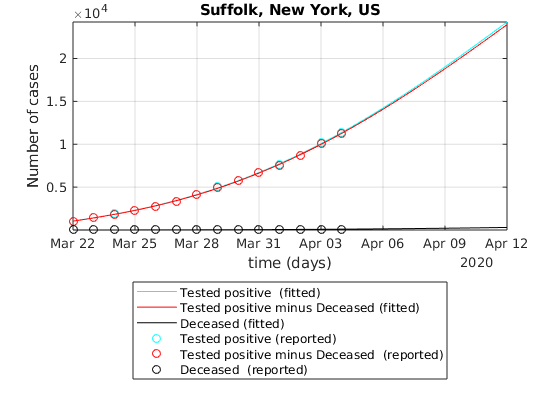

           Combined_Key        
    ___________________________

    "Westchester, New York, US"



Population = 967506 


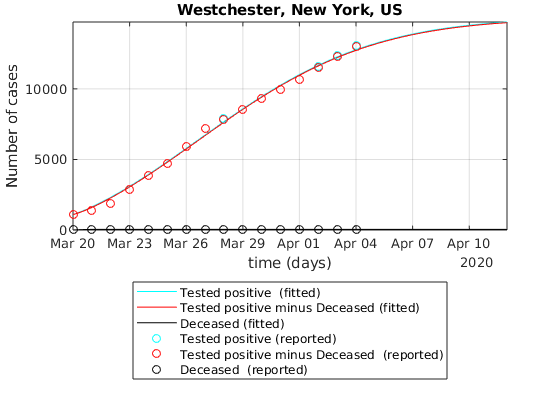

              Combined_Key          
    ________________________________

    "Philadelphia, Pennsylvania, US"



Population = 1584064 


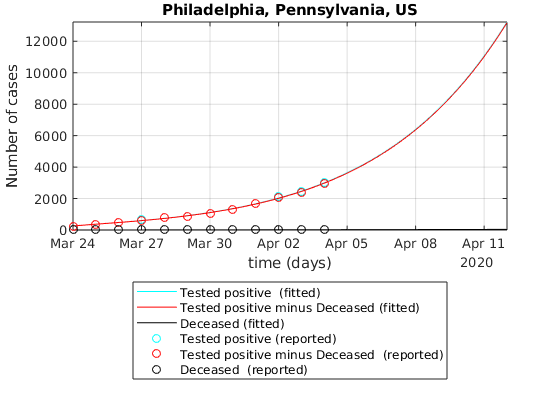

         Combined_Key     
    ______________________

    "King, Washington, US"



Population = 2252782 


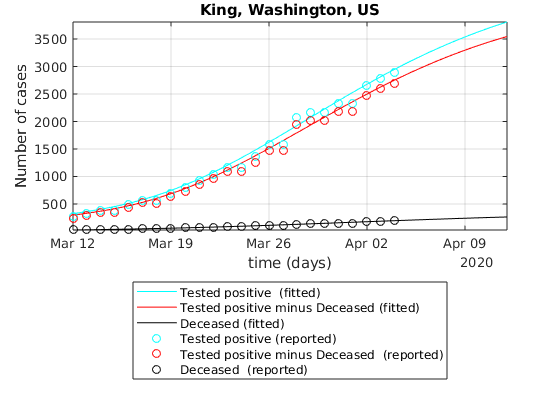

            Combined_Key        
    ____________________________

    "Unassigned, New Jersey, US"



Population = 1000000 


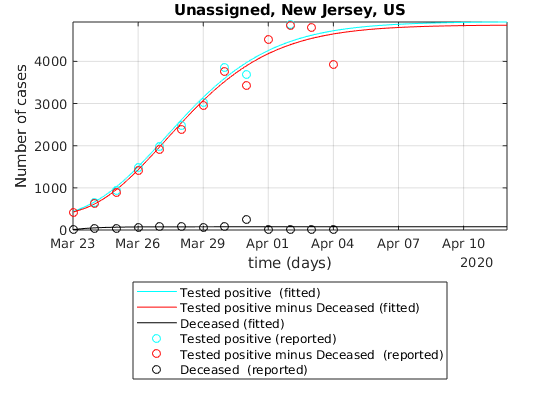

for ii = 2:numel(tableConfirmed.Combined_Key)
    
    Location = tableConfirmed.Combined_Key(ii);
    
    indC = find(strcmpi(tableConfirmed.Combined_Key,Location)==1);
    indD = find(strcmpi(tableDeaths.Combined_Key,Location)==1);
    
    Deaths = table2array(tableDeaths(indD,13:end));
    Confirmed = table2array(tableConfirmed(indC,12:end));
    Npop= table2array(tableDeaths(indD,12)); % p
    
    if Npop == 0
%         warning('Unreal population found. A dummy variable is used instead')
        Npop = 1e6; % dummy population is used instead
    end
    
    time = timeRef;
    minNum= round(0.075*max(Confirmed)); % 5% of the maximal number of confirmed is used for the initial conditions
    Deaths(Confirmed<=minNum)=[];
    time(Confirmed<=minNum)= [];
    Confirmed(Confirmed<=minNum)=[];
    
    
    if minNum>200 && numel(Confirmed) >10 % more than 10 days of good data
        disp(tableConfirmed(indC,11));
        fprintf(['Population = ',num2str(Npop),' \n'])
        % Definition of the first estimates for the parameters
        alpha_guess = 0.1;
        beta_guess = 0.8; % Infection rate
        LT_guess = 5; % latent time in days
        QT_guess = 21; % quarantine time in days
        lambda_guess = [0.08,0]; % recovery rate
        kappa_guess = [0.07,0.03]; % death rate
        
        guess = [alpha_guess,...
            beta_guess,...
            1/LT_guess,...
            1/QT_guess,...
            lambda_guess,...
            kappa_guess];
        
        E0 = Confirmed(1); % Initial number of exposed cases. Unknown but unlikely to be zero.
        I0 = Confirmed(1); % Initial number of infectious cases. Unknown but unlikely to be zero.
        Q0 = Confirmed(1);
        R0 = Deaths(1); % Unknown but unlikely to be zero. Taken as equal to the number of deaths
        D0 = Deaths(1);
        
        % Parameter estimation with the lsqcurvefit function
        [alpha1,beta1,gamma1,delta1,Lambda1,Kappa1] = ...
            fit_SEIQRDP(Confirmed-Deaths,[],Deaths,Npop,E0,I0,time,guess,'Display','off');
        
        dt = 0.1; % time step
        time1 = datetime(time(1)):dt:datetime(datestr(floor(datenum(now))+datenum(7)));
        N = numel(time1);
        t = [0:N-1].*dt;
        [S,E,I,Q,R,D,P] = SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,Q0,R0,D0,t);
        
        
        figure
        semilogy(time1,Q+R+D,'c',time1,Q+R,'r',time1,D,'k');
        hold on
        semilogy(time,Confirmed,'co',time,Confirmed-Deaths,'ro',time,Deaths,'ko');
        % ylim([0,1.1*Npop])
        ylabel('Number of cases')
        xlabel('time (days)')
        leg = {'Tested positive  (fitted)','Tested positive minus Deceased (fitted)',...
            'Deceased (fitted)',...
            'Tested positive (reported)',...
            'Tested positive minus Deceased  (reported)','Deceased  (reported)'};
        legend(leg{:},'location','southoutside')
        set(gcf,'color','w')
        grid on
        axis tight
        title([Location])
        set(gca,'yscale','lin')
        
        pause(1)
    end
end